% Example usage
x_ini = 0;
x_final = 1;
T_ini = 0;
T_l = 1;
T_r = 0;
n_points = 11;
del_t = [0.1, 0.01, 0.001];
time = [0, 0.1, 0.5, 1, 5, 10];
alpha = 1;



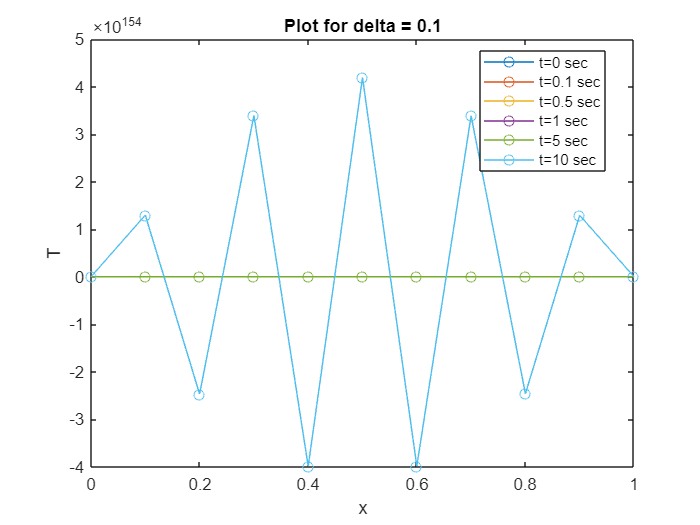

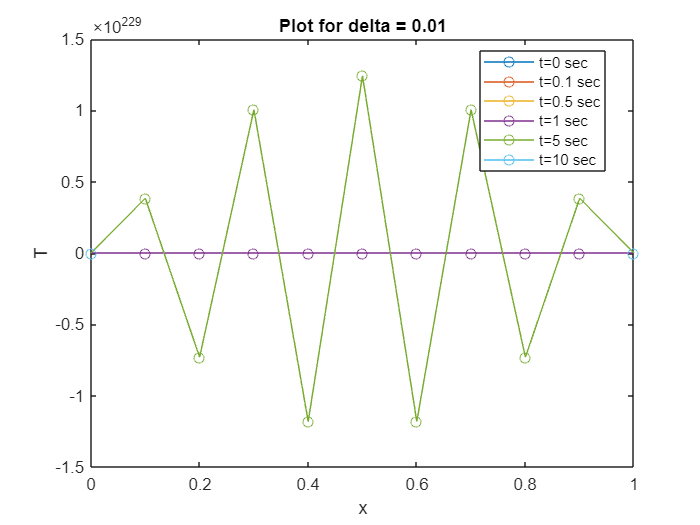

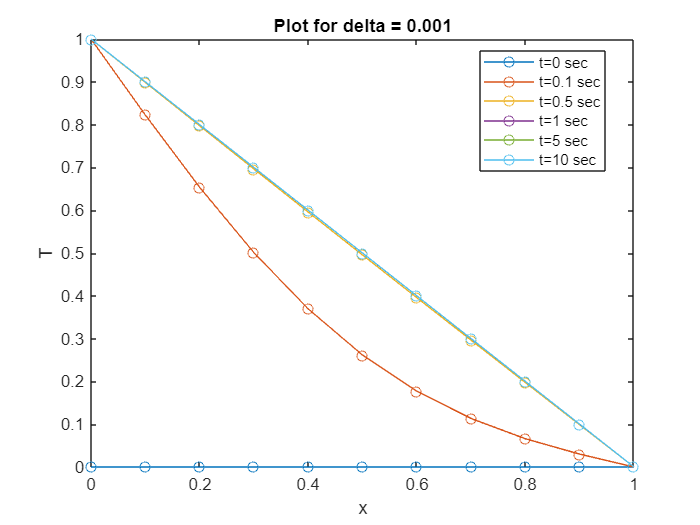


for t = 1:length(del_t)
    x_coordinate = linspace(x_ini, x_final, n_points);
    result = Assignment1_AM5630_ME21B145(x_ini, x_final, T_ini, T_l, T_r, n_points, del_t(t), alpha);
    
    figure; % Create a new figure for each del_t(t)
    
    for sec = 1:length(time)
        plot(x_coordinate, result((time(sec)/del_t(t)) + 1, :), '-o');
        hold on;
    end
    
    hold off;
    title(['Plot for delta = ', num2str(del_t(t))]);
    xlabel('x');
    ylabel('T');
    legend('t=0 sec', 't=0.1 sec', 't=0.5 sec', 't=1 sec', 't=5 sec', 't=10 sec', 'Location', 'best');
end